% Grid size
gridSize = 50;
grid = zeros(gridSize);

% Add random obstacles
numObstacles = 100; % Adjust as needed
obstacles = randperm(numel(grid), numObstacles);
grid(obstacles) = 1; % 1 represents obstacles

% Define start and goal points
start = [30, 45]; % Starting point
goal = [20, 30];  % Goal point
grid(start(1), start(2)) = 2; % 2 represents start
grid(goal(1), goal(2)) = 3;   % 3 represents goal

% Initialize open and closed sets with parent field
openSet = [];
openSet(1).pos = start;
openSet(1).g = 0;
openSet(1).parent = [];
closedSet = [];

% Visualize initial grid
figure;
imagesc(grid);
colormap([1 1 1; 0 0 0; 0 1 0; 1 0 0]); % Colors for free, obstacles, start, goal
axis equal;
hold on;

% Main Dijkstra loop
while ~isempty(openSet)
    % Find node with the lowest g-score (cost from start)
    [~, idx] = min([openSet.g]);
    current = openSet(idx);
    
    % Check if goal is reached
    if isequal(current.pos, goal)
        disp('Goal reached !');
        break;
    end
    
    % Move current node to closed set
    closedSet = [closedSet; current];
    openSet(idx) = [];
    
    % Get neighbors (up, down, left, right)
    neighbor_offsets = [0 1; 1 0; 0 -1; -1 0];
    neighbors = neighbor_offsets + current.pos;
    
    for i = 1:size(neighbors, 1)
        neighbor = neighbors(i, :);
        
        % Skip if out of bounds
        if neighbor(1) < 1 || neighbor(2) < 1 || ...
           neighbor(1) > gridSize || neighbor(2) > gridSize
            continue;
        end
        
        % Skip if obstacle or in closed set
        if grid(neighbor(1), neighbor(2)) == 1 || ...
           any(arrayfun(@(x) isequal(x.pos, neighbor), closedSet))
            continue;
        end
        
        % Calculate g score (Dijkstra's cost)
        tentative_g = current.g + 1;
        
        % Check if neighbor is in open set
        existing = arrayfun(@(x) isequal(x.pos, neighbor), openSet);
        if ~any(existing)
            % Add neighbor to open set
            openSet(end+1).pos = neighbor; %#ok<SAGROW>
            openSet(end).g = tentative_g;
            openSet(end).parent = current.pos;
        else
            idx_neighbor = find(existing);
            if tentative_g < openSet(idx_neighbor).g
                % Update neighbor with better path
                openSet(idx_neighbor).g = tentative_g;
                openSet(idx_neighbor).parent = current.pos;
            end
        end
    end
    
    % Update visualization
    plot(current.pos(2), current.pos(1), 'bo'); % Show path exploration
    drawnow;
    pause(0.001); % Adjust speed if needed
end

Goal reached !


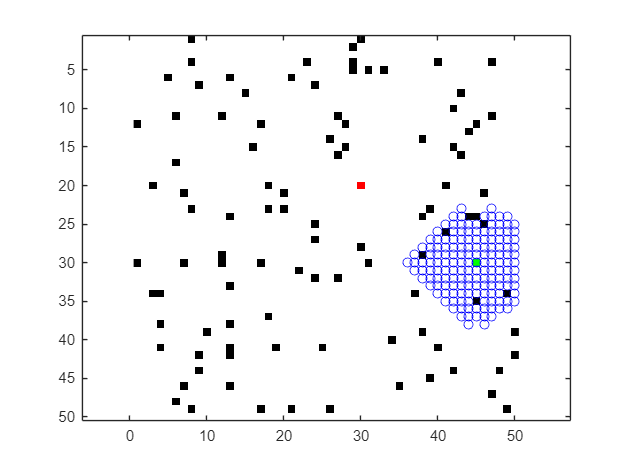


% Highlight the final path
if isequal(current.pos, goal)
    path = [current.pos];
    while ~isempty(current.parent)
        parent_pos = current.parent;
        idx = find(arrayfun(@(x) isequal(x.pos, parent_pos), closedSet), 1);
        if isempty(idx)
            error('Failed to trace back path: no matching parent node found.');
        end
        current = closedSet(idx);
        path = [current.pos; path]; %#ok<AGROW>
    end
    % Plot the final path
    plot(path(:, 2), path(:, 1), 'r', 'LineWidth', 2);
else
    disp('No path found!');
end